clc; clear;

% Parameters
N = 2e4;  % Total number of bits (use even number for QPSK)
SNR_dB_range = 0:2:30;
ber_zf = zeros(size(SNR_dB_range));
ber_knn = zeros(size(SNR_dB_range));
ber_svm = zeros(size(SNR_dB_range));
path_loss = 10;  % Scalar for simple THz attenuation

% Generate random bitstream and reshape into pairs
bits = randi([0 1], N, 1);        % Random 0s and 1s
bit_pairs = reshape(bits, [], 2); % Group bits into pairs (1 symbol = 2 bits)

% Map bit pairs to QPSK symbols
symbol_map = [1+1i, -1+1i, -1-1i, 1-1i] / sqrt(2);  % Normalized QPSK
indices = bit_pairs(:,1)*2 + bit_pairs(:,2) + 1;    % Convert bit pairs to 1-4
modulated_symbols = symbol_map(indices);           % QPSK complex symbols

% Simulation loop
for i = 1:length(SNR_dB_range)
    SNR_dB = SNR_dB_range(i);
    SNR_linear = 10^(SNR_dB/10);
    noise_power = 1 / SNR_linear;

    % Add complex Gaussian noise
    noise = sqrt(noise_power/2) * (randn(size(modulated_symbols)) + 1i*randn(size(modulated_symbols)));
    received = modulated_symbols ./ sqrt(path_loss) + noise;

    % --- Zero-Forcing Detection ---
    rx_zf = received * sqrt(path_loss);  % Reverse channel gain
    dec_real = real(rx_zf) > 0;
    dec_imag = imag(rx_zf) > 0;
    zf_detected = [dec_real, dec_imag];
    zf_bits = reshape(zf_detected.', [], 1);
    ber_zf(i) = sum(bits ~= zf_bits) / N;

    % --- Feature Preparation for ML ---
    received = received(:);
    X = [real(received), imag(received), abs(received)];
    Y = indices - 1;
    
    
    % Now apply PCA
    [~, X_pca] = pca(X);

    
    % Safely select top principal components (1 or 2)
    X_reduced = X_pca(:, 1:min(2, size(X_pca,2)));

    % Train-test split
    split = floor(0.8 * length(X));
    X_train = X_reduced(1:split,:);
    Y_train = Y(1:split);
    X_test = X_reduced(split+1:end, :);
    Y_test = Y(split+1:end);

    % --- k-NN Classification ---
    mdl_knn = fitcknn(X_train, Y_train, 'NumNeighbors', 5);
    pred_knn = predict(mdl_knn, X_test);
    temp_knn = de2bi(pred_knn, 2, 'left-msb');
    pred_bits_knn = reshape(temp_knn.', [], 1);
    ber_knn(i) = sum(pred_bits_knn ~= bits(split*2+1:end)) / (N - split*2);

    % --- SVM Classification ---
    mdl_svm = fitcecoc(X_train, Y_train, 'Learners', templateSVM('KernelFunction','linear'));
    pred_svm = predict(mdl_svm, X_test);
    temp_svm = de2bi(pred_svm, 2, 'left-msb');
    pred_bits_svm = reshape(temp_svm.', [], 1);
    ber_svm(i) = sum(pred_bits_svm ~= bits(split*2+1:end)) / (N - split*2);

    % Display progress
    fprintf('SNR = %2d dB | ZF: %.4f | k-NN: %.4f | SVM: %.4f\n', ...
        SNR_dB, ber_zf(i), ber_knn(i), ber_svm(i));
end

SNR =  0 dB | ZF: 0.5019 | k-NN: 0.4968 | SVM: 0.5040
SNR =  2 dB | ZF: 0.4991 | k-NN: 0.5010 | SVM: 0.5105
SNR =  4 dB | ZF: 0.5003 | k-NN: 0.5008 | SVM: 0.5005
SNR =  6 dB | ZF: 0.5033 | k-NN: 0.5022 | SVM: 0.4943
SNR =  8 dB | ZF: 0.5011 | k-NN: 0.4945 | SVM: 0.5018
SNR = 10 dB | ZF: 0.4989 | k-NN: 0.4923 | SVM: 0.4980
SNR = 12 dB | ZF: 0.4986 | k-NN: 0.5068 | SVM: 0.5005
SNR = 14 dB | ZF: 0.4979 | k-NN: 0.5040 | SVM: 0.5025
SNR = 16 dB | ZF: 0.4970 | k-NN: 0.5098 | SVM: 0.5068
SNR = 18 dB | ZF: 0.4985 | k-NN: 0.5050 | SVM: 0.5055
SNR = 20 dB | ZF: 0.4981 | k-NN: 0.5025 | SVM: 0.5030
SNR = 22 dB | ZF: 0.4980 | k-NN: 0.5032 | SVM: 0.5032
SNR = 24 dB | ZF: 0.4980 | k-NN: 0.5032 | SVM: 0.5032
SNR = 26 dB | ZF: 0.4980 | k-NN: 0.5032 | SVM: 0.5032
SNR = 28 dB | ZF: 0.4980 | k-NN: 0.5032 | SVM: 0.5032
SNR = 30 dB | ZF: 0.4980 | k-NN: 0.5032 | SVM: 0.5032


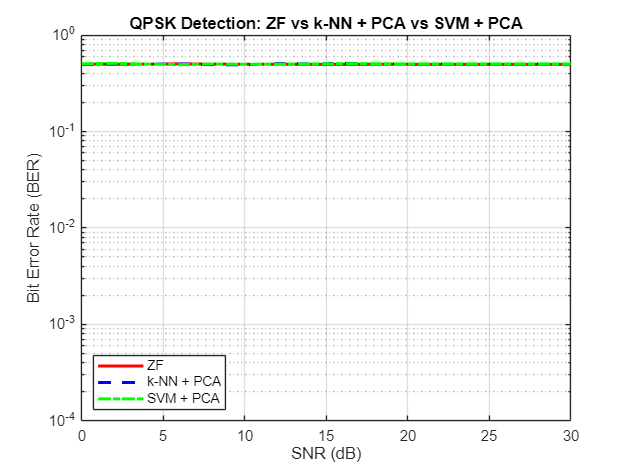

% --- Plotting the BER curves ---
figure;
semilogy(SNR_dB_range, ber_zf, 'r-', 'LineWidth', 2); hold on;
semilogy(SNR_dB_range, ber_knn, 'b--', 'LineWidth', 2);
semilogy(SNR_dB_range, ber_svm, 'g-.', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('QPSK Detection: ZF vs k-NN + PCA vs SVM + PCA');
legend('ZF', 'k-NN + PCA', 'SVM + PCA', 'Location', 'southwest');
grid on;
ylim([1e-4 1]);